clc;
clear;
close all;

%% DEFINITION OF SYSTEM

%Number of agents
m = 3;
%Number of state variables
n = 4;
%Overall dimension of the system         
v = m*n;

%Number of state variables seen by each observer
numberOfOnes_C = int8(n/4);
%Maximum number of connections in the graph for each observer
numberOfOnes_E = int8(m/2);

% Get a list of random locations, with no number repeating.
for i = 1:m
    indexes_C = randperm(n);
    indexes_E = randperm(m);
    
    % Start off with all zeros.
    c = zeros(1, n);
    e = zeros(1, m);
    
    % Now make half of them, in random locations, a 1.
    c(indexes_C(1:numberOfOnes_C)) = 1;
    e(indexes_E(1:numberOfOnes_E)) = 1;
    
    %Output Matrix
    C(i,:) = c;
    
    E(i,:) = e; % ones(1,m);                    
    E(i,i) = 0;
end

%State Matrices
A = randi([0, 1], n)

A =      0     1     1     1
     0     0     1     0
     0     1     1     0
     1     1     1     0


C

C =      0     0     1     0
     1     0     0     0
     0     0     1     0


E = [    0     1 0
          1     0     1
          1     0     0]

E =      0     1     0
     1     0     1
     1     0     0



%Check the Jointly Observability
O = obsv(A,C);

if n == rank(O) 
    disp("System is Jointly Observable")
else
    disp("System is not Jointly Observable")
end 

System is Jointly Observable


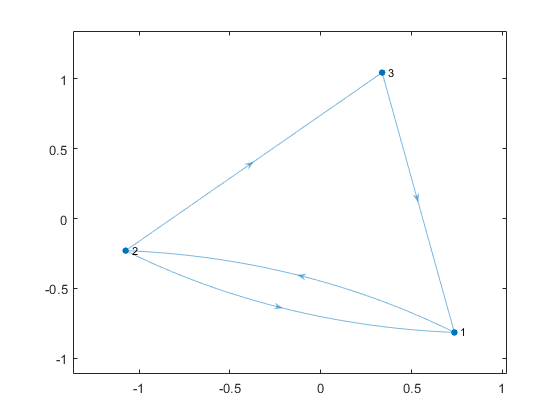


%Check the strongly connected components
GraphE = digraph(E);
plot(GraphE)

s = conncomp(GraphE);

if s == ones(1,m)
    disp("Graph is strongly connected")
else
    disp("Graph is weakly connected")
end

Graph is strongly connected




%% DEFINITION OF MATRICES FOR OBSERVERS

%Kronecker product for matrix A
Abig = kron(eye(m),A);

%The transpose of incidence matrix of communication graph 
Ebig = E';         
Ebig =  kron(Ebig, eye(n))

Ebig =      0     0     0     0     1     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     0     1     0     0
     0     0     0     0     0     0     1     0     0     0     1     0
     0     0     0     0     0     0     0     1     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0



%Matrices defined by unit vector in position k
Bbig = kron(eye(n), eye(m))

Bbig =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0



%state feedback controller gain matrix
poles = -2*ones(1,n); %desired poles
Kgain = place(A',eye(n),poles);

F = eye(n*m);
K = kron(eye(m), diag(Kgain));

Kbig = [K -F];

%Definition of C_
for i = 1:m
    
    zeroVectorForward = zeros(1,n*(m-i));
    zeroVectorBackward = zeros(1,n*(i-1));
    if( i > 1 ) 
        Cbig(i,:) = [zeroVectorBackward C(i,1:n) zeroVectorForward];
    elseif (i == 1)
        Cbig(i,:) = [C(i,1:n) zeroVectorForward];
    elseif (i == m)
        Cbig(i,:) = [zeroVectorBackward C(i,1:n)]; 
    end
end

Cbig = [Cbig ; Ebig];

H = Abig -Kbig*Cbig;

%%%CHECK
H_check = Abig;

%Observers and Neighbours
for i = 1:m
       
    if( i < 2)
        k = i;
    else
        k = (i-1)*n +1;
    end
    
    S = Bbig(1:v,k:n*i)*F(k:n*i,k:n*i)*Ebig(k:n*i,1:v) -Bbig(1:v,k:n*i)*K(k:i*n,i)*C(i,1:n)*Bbig(1:v,k:n*i)';
        
    H_check = H_check + S;
end

H_check = H_check - H;

if H_check == zeros(v,v)
    disp("H finds with H = Abig -Kbig*Cbig it is equal than the H defined in the paper")
end

H finds with H = Abig -Kbig*Cbig it is equal than the H defined in the paper


System (Ebig, H, Bbig) is Observable and Controllable



csys =
 
  A = 
         x1   x2   x3   x4   x5   x6   x7   x8   x9  x10  x11  x12
   x1     0    0    0    0    0    0    0    0    0    0    0   -6
   x2     1    0    0    0    0    0    0    0    0    0    0   14
   x3     0    1    0    0    0    0    0    0    0    0    0   20
   x4     0    0    1    0    0    0    0    0    0    0    0  -13
   x5     0    0    0    1    0    0    0    0    0    0    0  -16
   x6     0    0    0    0    1    0    0    0    0    0    0   -7
   x7     0    0    0    0    0    1    0    0    0    0    0   -9
   x8     0    0    0    0    0    0    1    0    0    0    0    5
   x9     0    0    0    0    0    0    0    1    0    0    0   16
   x10    0    0    0    0    0    0    0    0    1    0    0    4
   x11    0    0    0    0    0    0    0    0    0    1    0   -7
   x12    0    0    0    0    0    0    0    0    0    0    1   -5
 
  B = 
             u1       u2       u3       u4
   x1         1   -2.001    2.401  -0.2523
   x2         0  

T =     1.0000   -2.0008    2.4007   -0.2523    0.2523    0.0877    0.2358   -1.9459   -0.6126    5.0051   -2.1246    0.7027
         0    7.8316   -8.5151   -2.5676    3.5676    1.5307   -1.6361    1.9550    5.2883  -15.2385    5.8864   -4.5856
         0   -2.4916    0.7758   -0.1216    0.1216   -3.6099    1.4651    0.5856   -1.5811   -3.3047    2.6723   -0.3874
         0   -7.3937    7.5210    2.5766   -2.5766   -5.5774    3.8233   -2.1712   -4.8378    8.0588   -1.9244    2.1081
         0   -1.6675    1.5674    0.9144   -0.9144   -1.2456    1.0691    0.0541   -1.1126    0.0051    0.3754   -0.2973
         0   -2.5045    2.2207    0.3829   -0.3829   -0.4955    0.0225   -0.1892   -1.6892    3.6126   -1.3829    0.8739
         0   -0.7579    1.3488   -0.2207    0.2207    1.2217   -1.0292   -1.0360   -0.2027    4.4266   -2.3445    0.8649
         0    4.8324   -4.5825   -1.6486    1.6486    2.7763   -1.8719    0.5676    3.2342   -5.2436    1.3443   -1.6216
         0    2.7893   -3.21

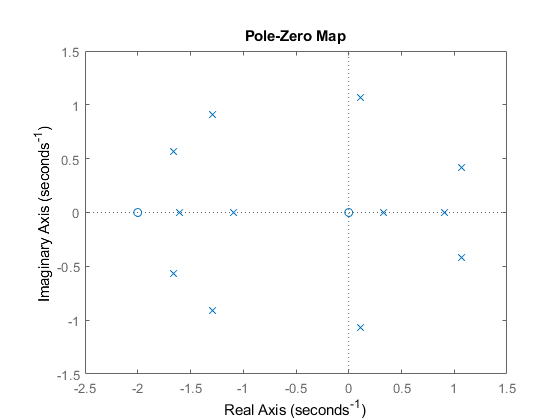


%%Observability and Controllability of the total system
Obar = obsv(H,Ebig(1:n,1:v));
Rbar = ctrb(H,Bbig(1:v,1:n));

if v == rank(Obar) && v == rank(Rbar)
    disp("System (Ebig, H, Bbig) is Observable and Controllable")
    
    
    sys = ss(H,Bbig(1:v,1:n),Ebig(1:n,1:v),zeros(n,n));
    [csys,T]= canon(sys,'companion')
    
    pzmap(csys)
    
    
elseif  v == rank(Obar) && v ~= rank(Rbar)
    disp("System (Ebig, H, Bbig) is Observable and not Controllable")
elseif  v == rank(Rbar) && v ~= rank(Obar)
    disp("System (Ebig, H, Bbig) is Controllable and not Observable")
else
    disp("System (Ebig, H, Bbig) is nor Controllable neither Observable")
end



%obs_poles = -2*ones(1,v); %desired poles
%Kgain_obs = place(Abig',Cbig',obs_poles);

%H = Abig - Kgain_obs*Cbig;




